clear
clc
load robotData.mat

% Visualize the given Data
plotSensors(sensor1,label);
plotSensors(sensor2,label);

% Concatenate and transpose data
bothSensor = [sensor1 sensor2]';
labelRow  = label';
summary(labelRow)

     Move-Forward      Sharp-Right-Turn      Slight-Left-Turn      Slight-Right-Turn 
     2205              2097                   328                   826              


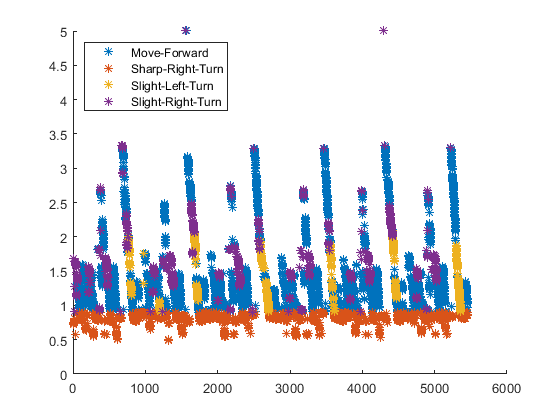

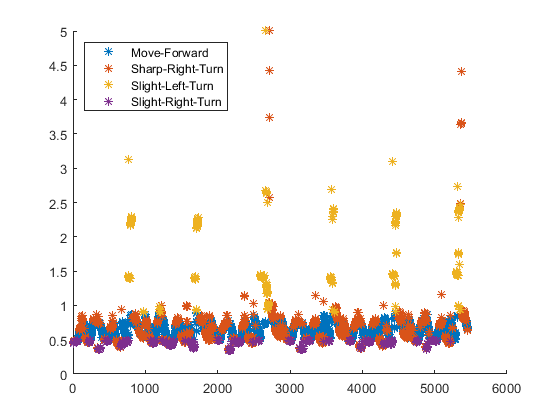

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:06 |       43.86% |       40.80% |       1.3561 |       1.6034 |          0.0100 |


|      50 |          50 |       00:02:59 |       71.39% |       67.80% |       0.6846 |       0.7653 |          0.0100 |


|     100 |         100 |       00:05:55 |       90.09% |       86.40% |       0.2740 |       0.4515 |          0.0100 |


|     150 |         150 |       00:08:51 |       91.96% |       89.00% |       0.1979 |       0.3580 |          0.0100 |


|     200 |         200 |       00:11:46 |       85.19% |       83.00% |       0.3931 |       0.4518 |          0.0100 |


|     250 |         250 |       00:14:43 |       95.02% |       92.80% |       0.1431 |       0.2726 |          0.0100 |


|     300 |         300 |       00:17:38 |       95.05% |       89.40% |       0.1261 |       0.3413 |          0.0100 |


|     350 |         350 |       00:20:33 |       97.30% |       91.20% |       0.0753 |       0.3457 |          0.0100 |


|======================================================================================================================|



% Create training,testing and validation sets
n = 1000;
m = 500;

XTrain = bothSensor(:,1:end-(n+m));
YTrain = labelRow(1:end-(n+m));

XValidation = bothSensor(:,end-(n+m)+1:end-n);
YValidation = labelRow(end-(n+m)+1:end-n);

XTest = bothSensor(:,end-n+1:end);
YTest = labelRow(end-n+1:end);


% Create the layers of the Bidirectional LSTM model
numFeatures = 2;
numHiddenUnits1 = 125;
numHiddenUnits2 = 100;  
numClasses = 4;
lstmLayer = [
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits1,'OutputMode','sequence')    
    dropoutLayer(0.2)
    lstmLayer(numHiddenUnits2,'OutputMode','sequence')
    dropoutLayer(0.2)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];
%Set the options of the model
options = trainingOptions(...
    'adam', ...
    'MaxEpochs',350, ...
    'InitialLearnRate',0.01, ...
    'Plots','training-progress',...
    'ValidationData',{XValidation,YValidation}, ...
    'ValidationFrequency',50);
%   'LearnRateSchedule','piecewise'...
%   'GradientThreshold',1, ...
%    'Shuffle','every-epoch', ...
%     'LearnRateDropPeriod',200,...
%Train the model
net = trainNetwork(XTrain,YTrain,lstmLayer,options);


%Evaluate Model
prediction = classify(net,XTest);
accuracy = nnz(prediction == YTest)/numel(YTest)

accuracy = 0.9290

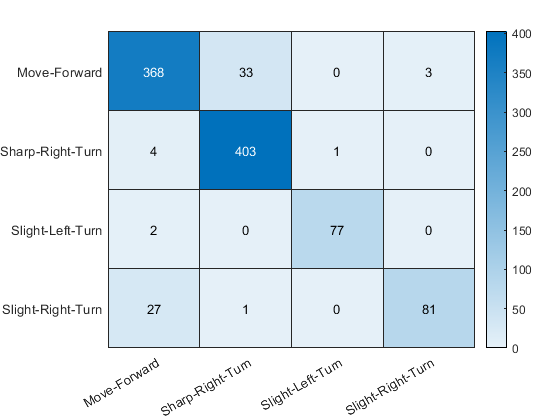



% Train the model and evaluate in a double for loop for different epoch and learning rate
% Set v in format:starting epoch: range of epoch: final epoch
% Set W in format:starting learning rate:range learning rate:final learning rate
    
%     v = 1:499:500
%     w = 0.001:0.001:0.001
%     testAllModels(v,w,XTrain,YTrain,XTest,YTest,bilstmLayer,options)

%Visualize the result
[cmap,clabel] = confusionmat(YTest,prediction);
hmap = heatmap(clabel,clabel,cmap);

function testAllModels(v,w,XTrain,YTrain,XTest,YTest,bilstmLayer,options)
fileID = fopen('Result','w');
    for epoch = v
        for rate = w 
            %Train the model
            net = trainNetwork(XTrain,YTrain,bilstmLayer,options);
            
            %Evaluate Model
            prediction = classify(net,XTest);
            accuracy = nnz(prediction == YTest)/numel(YTest)
            
            %Create a txt document with the accuracy
            accDisp = ['Accuracy_' num2str(epoch,'%.2f') '_' ...
                        num2str(rate,'%.3f') '.doc'];
            fprintf(fileID, accDisp);
            fprintf(fileID,'%.2f\n',accuracy);
    
        end
    end
fclose(fileID);
end

function plotSensors(X,Y)

    figure
    cat = categories(Y);
    
    for i = 1:length(cat)
        label = cat(i);
        idx = find(Y == label);
        hold on
        plot(idx,X(idx),'*')
    end
    
    hold off
    legend(cat,'Location','northwest')
    
end